# Optimise to Maxmise the Ampacity Using Surrogate Methods

This live script walks through the process to maximise the current carrying capacity of the conductor.  For simplicity the soil parameters have been hard coded but they can also be parametised to maximise the flexibility of the optimiser.

Surrogate methods can be particularly effective in cases like this where the objective function is expensive.  However, it is not assured to get the optimial solution but *close* to the optimal.  This "near" solution can then be used as an input to local optimisers to speed their search.

## Boilerplate

clearvars
kToC = 273.3;

## Bounds and Initial Conditions

### Amp Bounds

ub = 1000; % Upper bound
lb = 10; % Lower bound

### Temperature Bounds

tMax = 80; % in Celcius

% Convert to Kelvin
tMax = tMax + kToC;

### Start Point

amp0 = 300; % Amps

## Set Up the Function Handle and Number of Variables

minFunc = @(amp)objConstructor(amp, tMax);
numVars = 1;

## Optimiser

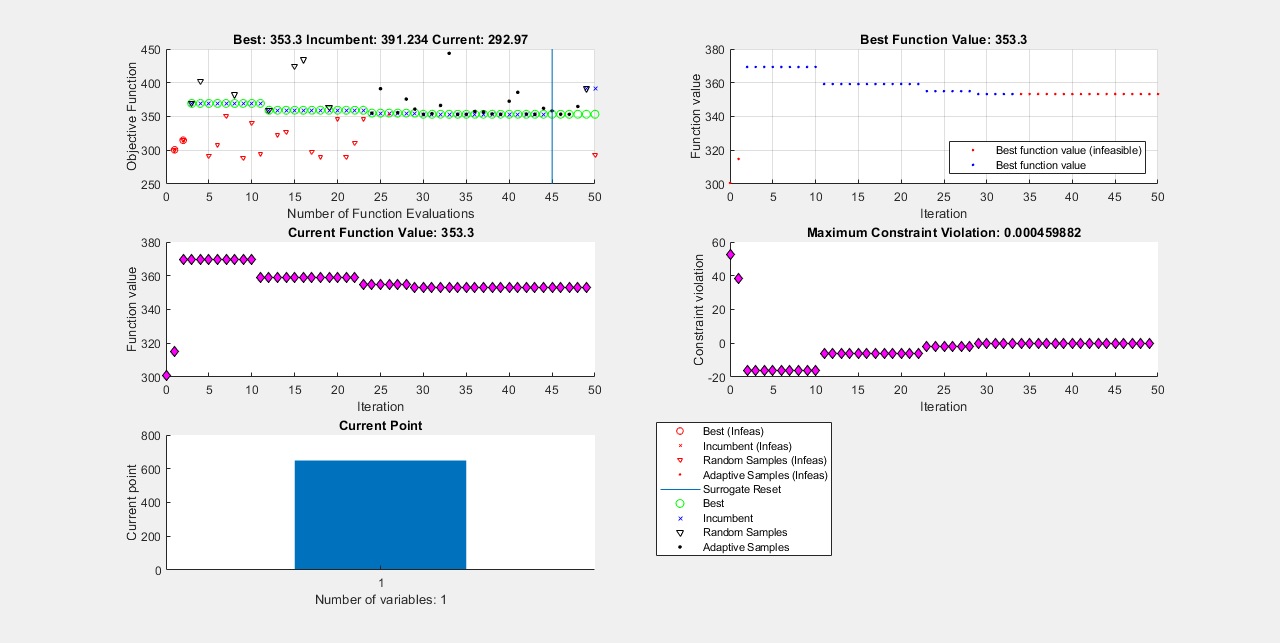

% Set nondefault solver options
options = optimoptions('surrogateopt','MaxFunctionEvaluations',50,...
    'UseParallel',true,'Display','off','PlotFcn',{'surrogateoptplot',...
    'optimplotfvalconstr','optimplotfval','optimplotconstrviolation',...
    'optimplotx'});

% Solve
[solution,objectiveValue] = surrogateopt(minFunc,repmat(lb,numVars),...
    repmat(ub,numVars),[],options);


% Clear variables
clearvars options

Copyright © 2020 The MathWorks, Inc.